# **    PZT Noise : Phase estimation with PZT Noise**

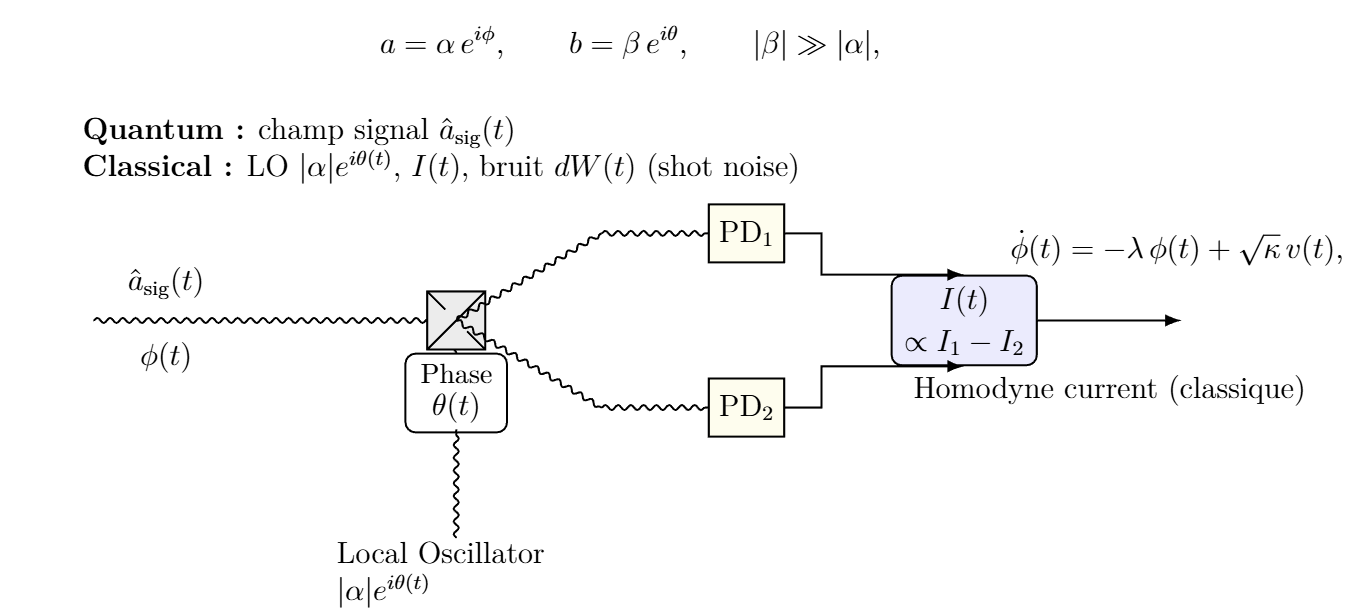

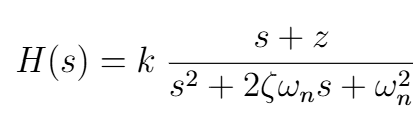

close all; clear; clc;

%% -------------------- User parameters --------------------
Ts    = 1e-3;          % sampling period [s]
N     = 20000;         % number of samples
alpha = 30;            % |alpha| (LO amplitude / effective coherent amplitude)

% PZ noise parameters (2nd order)
wn    = 2*pi*20;       % natural frequency [rad/s]
zeta  = 0.2;           % damping
z     = 2*pi*5;        % zero location (s + z)
k     = 1.0;           % gain

% Continuous-time white noise intensity: E[w(t)w(tau)] = qc*delta(t-tau)
qc    = 1.0;           % tune this to set phase-noise power

rng(1);

%% -------------------- Continuous-time PZ state-space --------------------
a1 = 2*zeta*wn;
a0 = wn^2;

b1 = k;
b0 = k*z;

A  = [0 1; -a0 -a1];
B  = [0; 1];                 % driven by w(t)
C  = [b0 b1];                % phi = C x
D  = 0;

% Put qc into input scaling (equivalent): w(t) = sqrt(qc)*wc(t), wc unit intensity
Bq = B*sqrt(qc);

sysc = ss(A,Bq,C,D);

%% -------------------- Discretization --------------------
sysd = c2d(sysc, Ts, 'zoh');
Ad   = sysd.A;
Gd   = sysd.B;    % this multiplies discrete-time white noise approx (see below)
Cd   = sysd.C;

nx = size(Ad,1);

%% -------------------- Measurement noise from homodyne --------------------
% Using z_k = Delta y / Ts approx phi_k + v_k, with v_k ~ N(0, R), R = 1/(4|alpha|^2 Ts)
R = 1/(4*alpha^2*Ts);

%% -------------------- Process noise covariance (discrete) --------------------
% We'll drive x_{k+1} = Ad x_k + Gd * eta_k, eta_k ~ N(0,1)
Qeta = 1;                 % scalar
Q    = Gd*Qeta*Gd.';       % nx-by-nx

%% -------------------- Simulate true system --------------------
x = zeros(nx, N);
phi = zeros(1, N);
zmeas = zeros(1, N);

for kidx = 2:N
    eta = randn;                          % unit variance
    x(:,kidx) = Ad*x(:,kidx-1) + Gd*eta;
    phi(kidx) = Cd*x(:,kidx);

    v = sqrt(R)*randn;
    zmeas(kidx) = phi(kidx) + v;
end

%% -------------------- Kalman filter (steady-state) --------------------
% dlqe gives steady-state gain for x_{k+1}=Ad x_k + Gd w_k, y_k=Cd x_k + v_k
% with cov(w_k)=Qeta, cov(v_k)=R
[Kk, Pk, ~] = dlqe(Ad, Gd, Cd, Qeta, R);   % Kk: nx-by-ny (ny=1)

xhatK = zeros(nx, N);
phiHatK = zeros(1, N);

for kidx = 2:N
    % predictor
    xpred = Ad*xhatK(:,kidx-1);

    % update (measurement at kidx)
    innov = zmeas(kidx) - Cd*xpred;
    xhatK(:,kidx) = xpred + Kk*innov;

    phiHatK(kidx) = Cd*xhatK(:,kidx);
end

%% -------------------- Luenberger observer (pole placement) --------------------
% Choose observer poles inside unit circle, typically faster than plant
% Heuristic: scale plant poles by factor <1 (faster), or pick explicit values.
plantPoles = eig(Ad);

% Example: pick two real poles a bit faster (more damping), ensure stable:
p1 = 0.6;
p2 = 0.7;
L = place(Ad', Cd', [p1 p2])';            % L: nx-by-1

xhatL = zeros(nx, N);
phiHatL = zeros(1, N);

for kidx = 2:N
    xhatL(:,kidx) = Ad*xhatL(:,kidx-1) + L*(zmeas(kidx-1) - Cd*xhatL(:,kidx-1));
    phiHatL(kidx) = Cd*xhatL(:,kidx);
end

%% -------------------- Metrics --------------------
burn = round(0.1*N);   % ignore transient
eK = phi(burn:end) - phiHatK(burn:end);
eL = phi(burn:end) - phiHatL(burn:end);

RMSE_K = sqrt(mean(eK.^2));
RMSE_L = sqrt(mean(eL.^2));

fprintf('RMSE Kalman     = %.4e rad\n', RMSE_K);

RMSE Kalman     = 3.3697e-03 rad


fprintf('RMSE Luenberger = %.4e rad\n', RMSE_L);

RMSE Luenberger = 3.7943e-01 rad


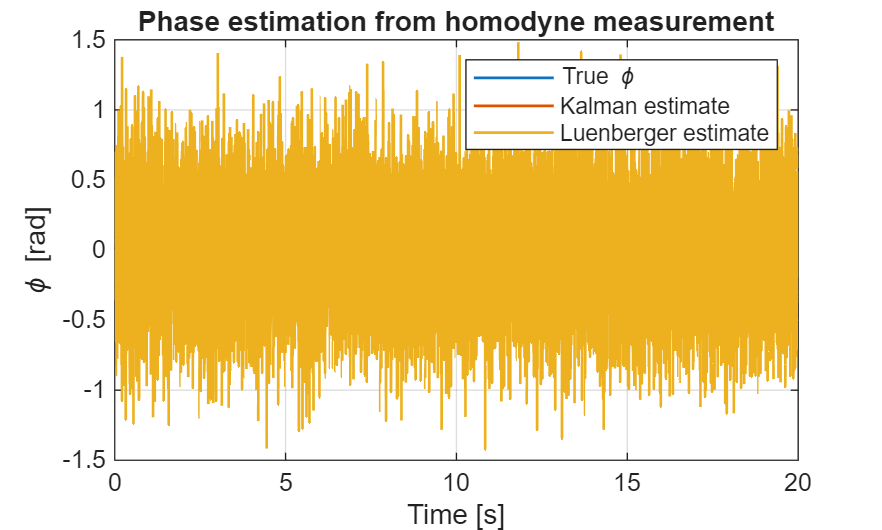


%% -------------------- Plots --------------------
t = (0:N-1)*Ts;

figure;
plot(t, phi, 'LineWidth', 1); hold on;
plot(t, phiHatK, 'LineWidth', 1);
plot(t, phiHatL, 'LineWidth', 1);
grid on;
xlabel('Time [s]'); ylabel('\phi [rad]');
legend('True \phi','Kalman estimate','Luenberger estimate');
title('Phase estimation from homodyne measurement');

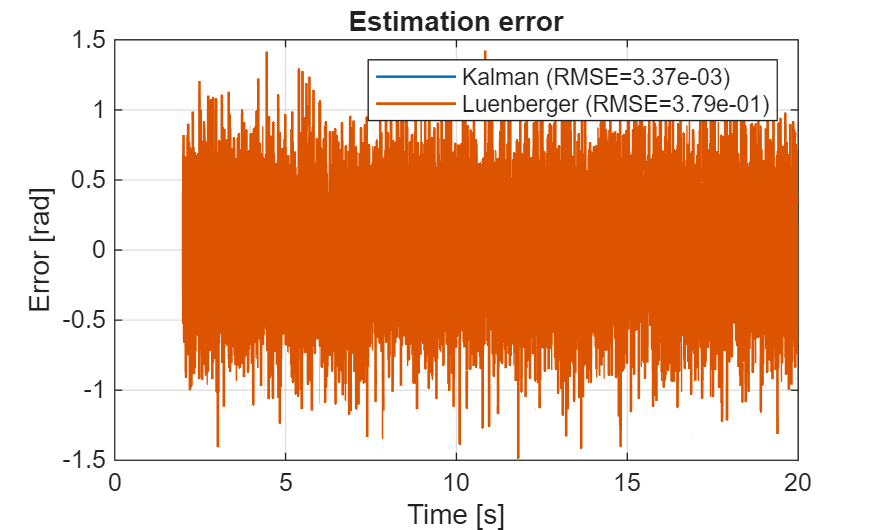


figure;
plot(t(burn:end), eK, 'LineWidth', 1); hold on;
plot(t(burn:end), eL, 'LineWidth', 1);
grid on;
xlabel('Time [s]'); ylabel('Error [rad]');
legend(sprintf('Kalman (RMSE=%.2e)',RMSE_K), sprintf('Luenberger (RMSE=%.2e)',RMSE_L));
title('Estimation error');

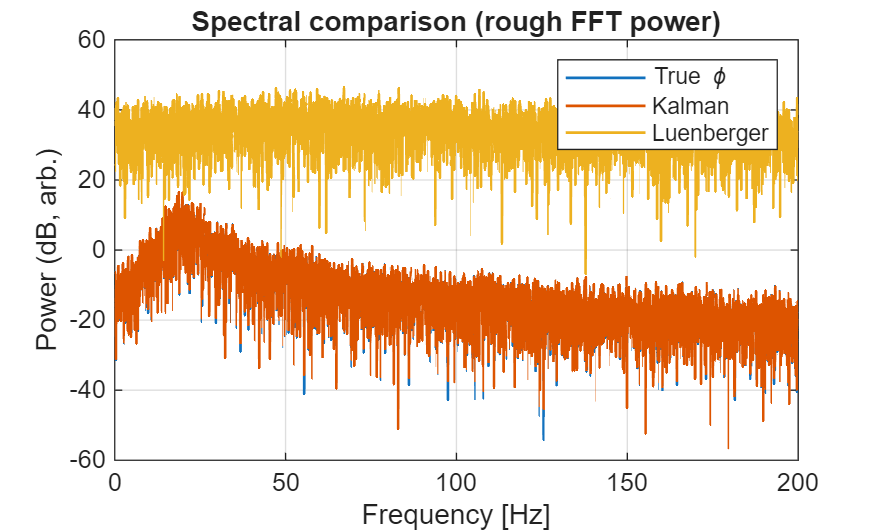


figure;
% PSD-ish quick view using FFT magnitude (rough)
Nfft = 2^nextpow2(length(phi(burn:end)));
F = (0:Nfft-1)/(Nfft*Ts);
PHI = abs(fft(phi(burn:end), Nfft)).^2;
EK  = abs(fft(eK, Nfft)).^2;
EL  = abs(fft(eL, Nfft)).^2;

plot(F(1:floor(Nfft/2)), 10*log10(PHI(1:floor(Nfft/2))+eps), 'LineWidth', 1); hold on;
plot(F(1:floor(Nfft/2)), 10*log10(EK(1:floor(Nfft/2))+eps), 'LineWidth', 1);
plot(F(1:floor(Nfft/2)), 10*log10(EL(1:floor(Nfft/2))+eps), 'LineWidth', 1);
grid on;
xlabel('Frequency [Hz]'); ylabel('Power (dB, arb.)');
legend('True \phi','Kalman','Luenberger');
title('Spectral comparison (rough FFT power)');
xlim([0 200]);